## Cold plate requirements and operating conditions

The cold plate has to carry away a heat load of a maximum of 2kW. The working fluid is water. The desired maximum temperature at the cooling plate inlet is 25°C and the outlet temperature should not exceed 20°C. The coolant loop is assumed to operate at a pressure of 2 bar. The device temperature should not exceed 50°C. 

#### Operating conditions

QDiss           = 2000;         % (W) Heat load
deltaTCoolant   = 5;            % (°C) Maximum temperature rise allowed
TCoolantIn      = 25;           % (°C) Assumed coolant inlet temperature
TCoolantOutMax  = 30;           % (°C) Maximum coolant outlet temperature
TSurfaceMax     = 50;           % (°C) Maximum device temperature
pLoop           = 2;            % (bar) Pressure in coolant loop

#### Water properties at 25°C

cpCoolant       = 4180.74;      % (J/(kg*K)) heat cpacity
rhoCoolant      = 997.137;      % (kg/m^3) density
muCoolant       = 8.89995e-4;   % Pa·s
kCoolant        = 0.607;        % W/(m*K)
PrCoolant       = 6.134;        % (1) Prandtl number

#### Required flow rate

The required steady-state flow rate to keep the outlet temperature at a maximum of 30°C with the assumed inlet temperature is determined using:


$$Q_{\textrm{Diss}} =\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{cp},\textrm{in}} \right)*{\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$


mDot    = QDiss/(cpCoolant*deltaTCoolant); % (kg/s) Mass flow rate
VDot    = mDot/rhoCoolant;                % (m^3/s) Volumetric flow rate
VDotLPM = mDot/rhoCoolant*1000*60;        % (l/min) Volumetric flow rate

#### Testing in a Simscape model

To test this in a simulation a simple model is build

open_system("example_TCoolantOut")

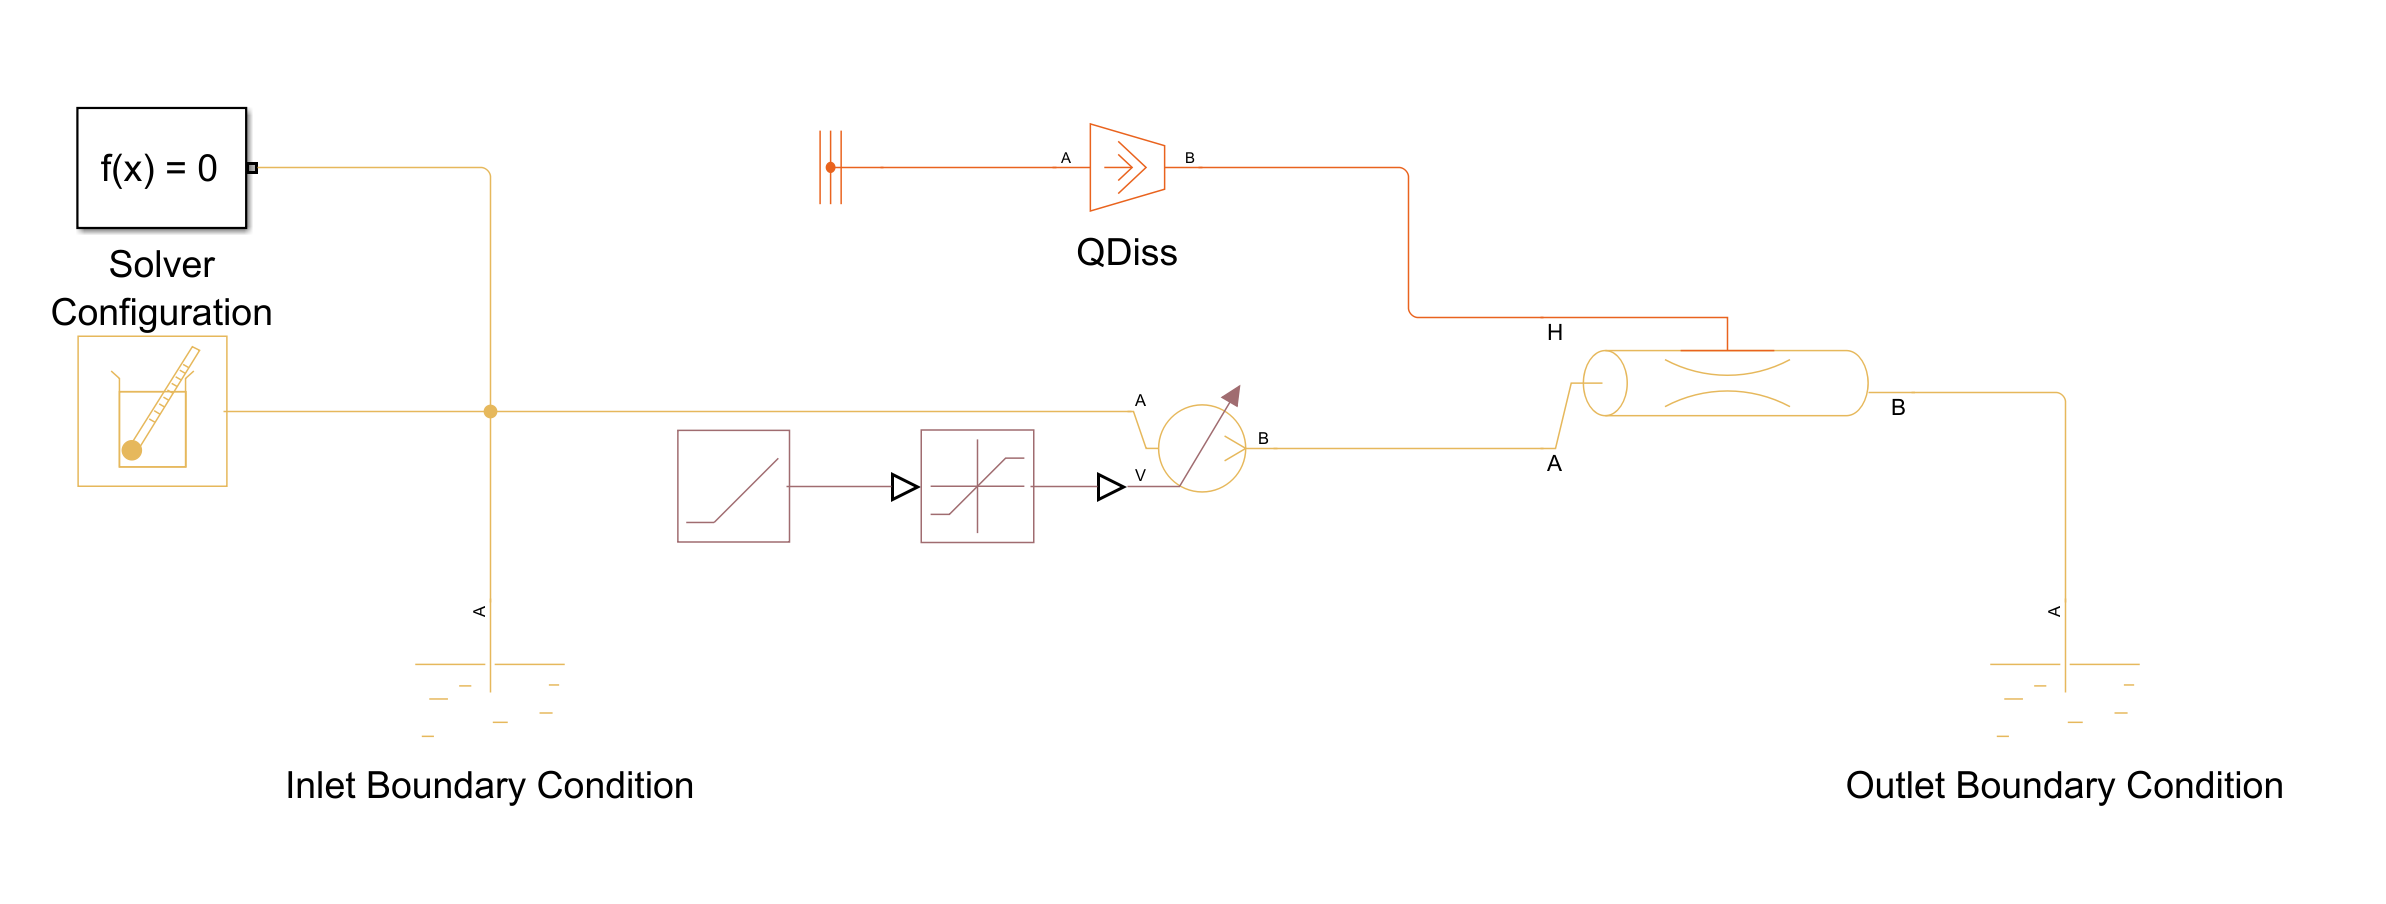

Two Reservoirs act as as inlet and outlet boundary conditions. Since we are only looking at results after the simulation has reached steady-state and are at this point not looking at pressure losses, we leave the pipe geometry parameters at the default values. The flow rate is created using a Flow Rate Source, we are starting from resting fluid and ramping up to the desired flow rate. We leave the model running for a long enough simulation time to reach steady state. An look at the result at the final result.

simInp = Simulink.SimulationInput("example_TCoolantOut");
simInp = simInp.setModelParameter("StopTime","7200");

simOut = sim(simInp);

Next, we'll extract resuts from the Simscape logging object. For the pipe block we can extract values for the ports (**A** and **B**) and since the block also has a internal fluid volume the node **T_I** will also be visible in the Simscape logging object. In the example we imposed a positive flow rate, meaning the flow will go from port A to port B in the pipe, therefore the temperature at port B will be the same as at port T_I. This is due to the [Upwinding Numerical Scheme](https://www.mathworks.com/help/releases/R2025a/hydro/ug/simscape-fluids-numerical-scheme.html) which is used in Simscape domains to carry along energy, species flows, etc. along with the mass flow. 

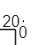

TPipeA = simOut.simlog.Pipe_TL.A.T.series.values('degC');
TPipeB = simOut.simlog.Pipe_TL.B.T.series.values('degC');
TPipeT_I = simOut.simlog.Pipe_TL.T_I.series.values('degC');

figure
plot(simOut.tout,[TPipeA,TPipeB,TPipeT_I])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax,TCoolantOutMax],'k:')
ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,In}','T_{Coolant,Out}','T_{Pipe,Internal}')
hold off

We can verify that the outlet temperature converges to the desired maximum outlet temperature and that the internal node value is consistent with the outlet node (**B**) temperature. 

#### Required thermal resistance for the required maximum device temperature

Next we will look at the necessary resistance that would ensure the device stays at its maximum allowed temperature of 50°C. For steady state the surface temperatute can be determined using


$$T_{\textrm{surface}} =Q_{\textrm{Diss}} *R_{\textrm{CP}} \;+T_{\textrm{cp},\textrm{out}}$$


Rcp = (TSurfaceMax - TCoolantOutMax)/QDiss;   % K/W

#### Testing in a Simscape model

We can replicate this in a Simscape model. 

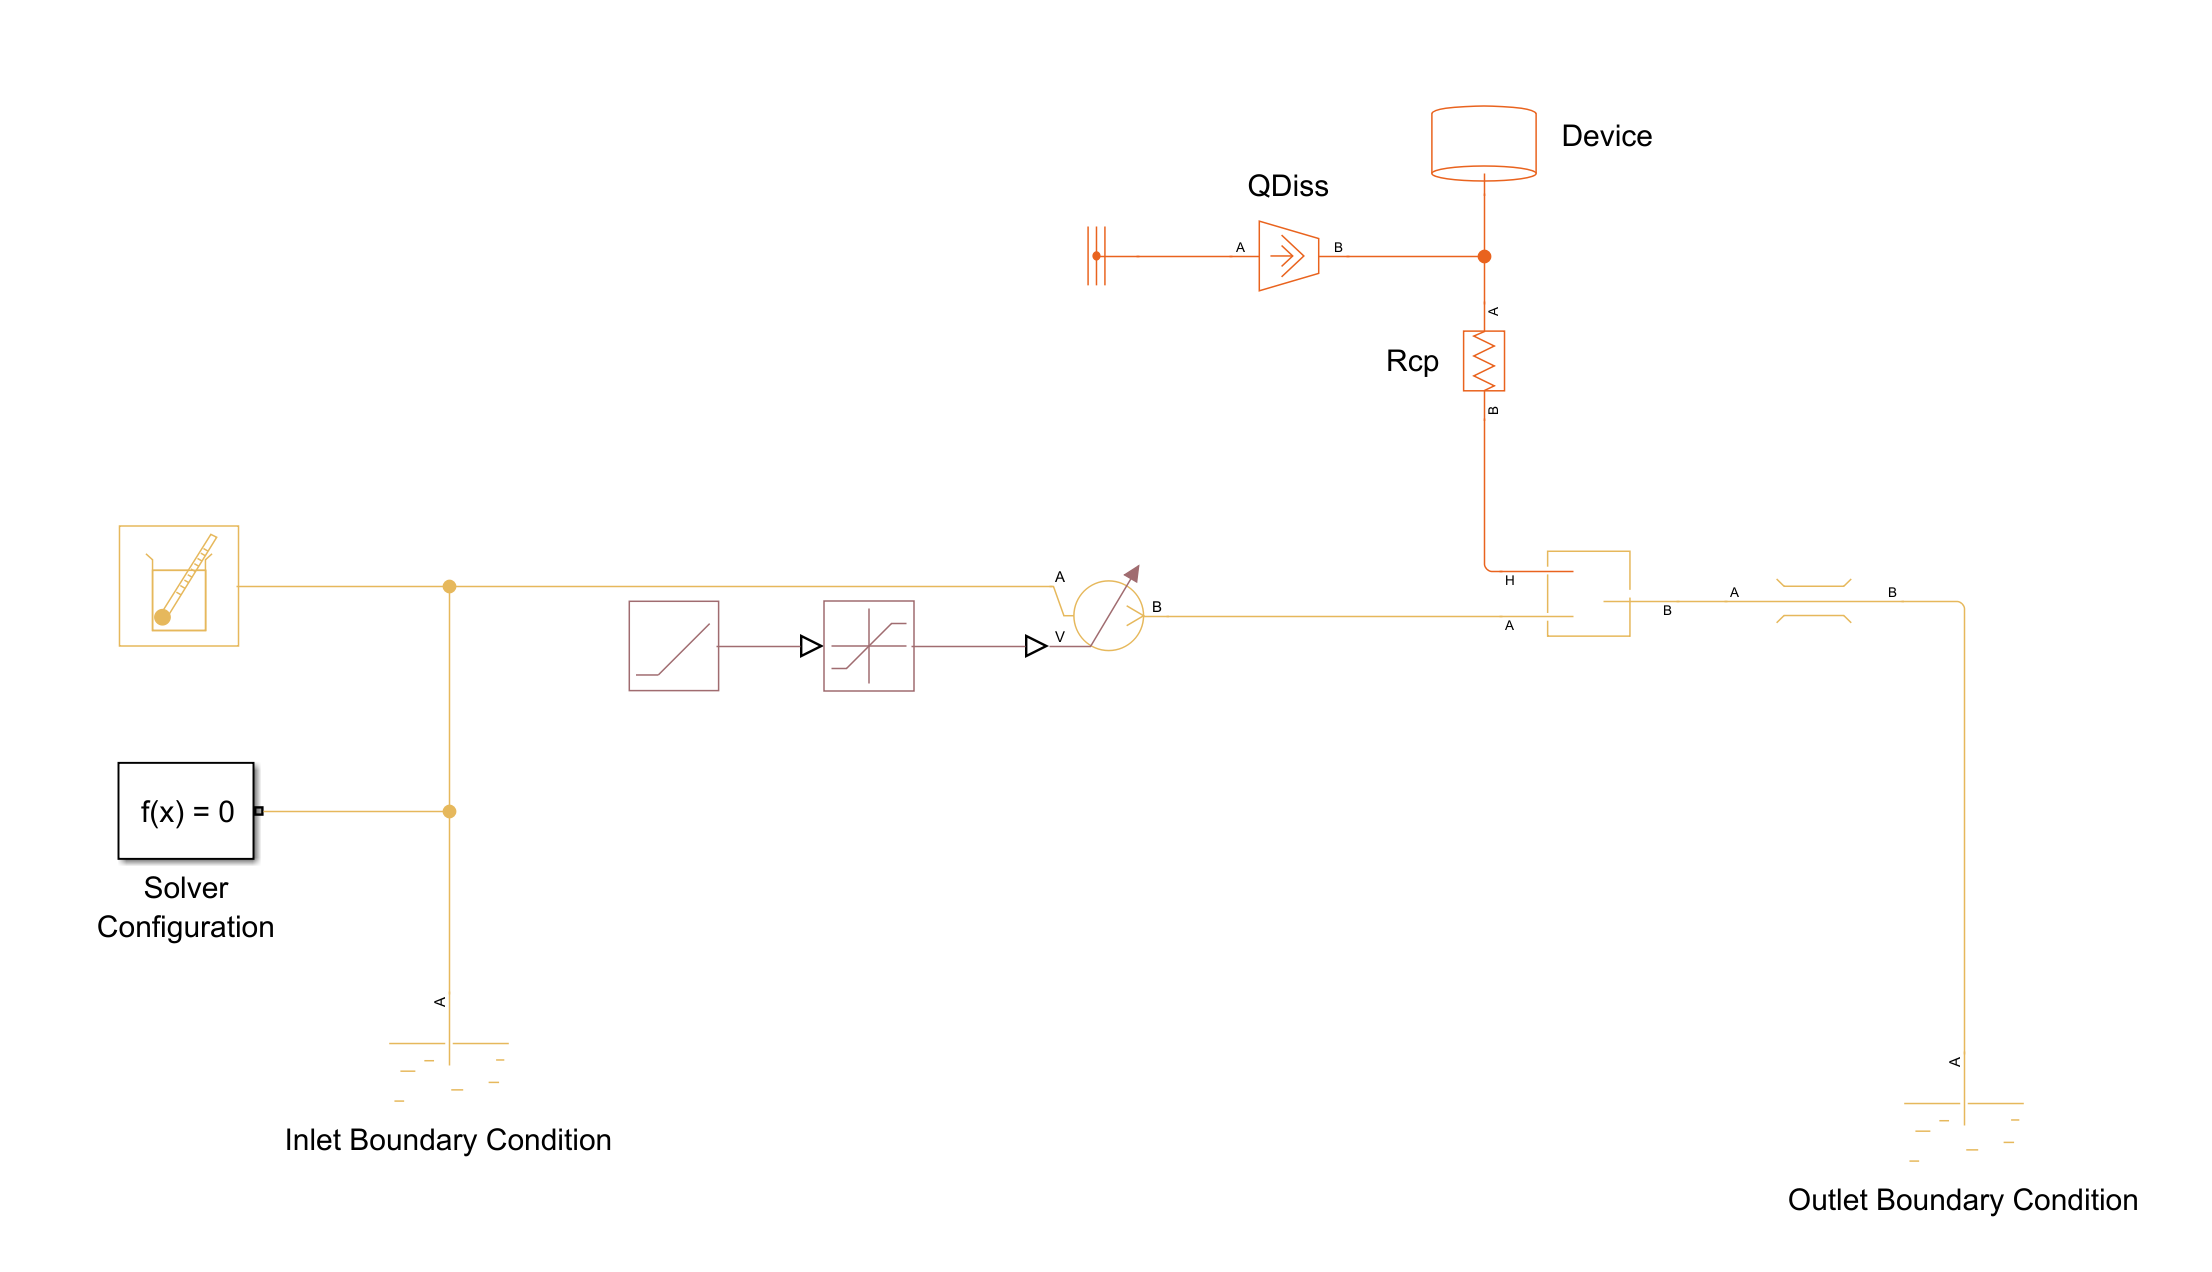

The cold plate fluid volume is here represented using a Constant Volume Chamber TL. In contrast to the Pipe TL block the thermal H port is directly connected to the internal fluid node, and there is no thermal resistance present. The Pipe TL block calculates convective heat transfer between its H port and the internal fluid volume. So to be able to test the overall thermal resistance value from convection and conduction, a Constant Volume Chamber TL block is used. Simlarly, since there is no restance between internal node and A and B port, therefore a Flow Resistance is added, to disconnect the internal node from the outlet boundary condition. (Link example Pipe vs. Chamber here??)

open_system("example_Rcp_Chamber")

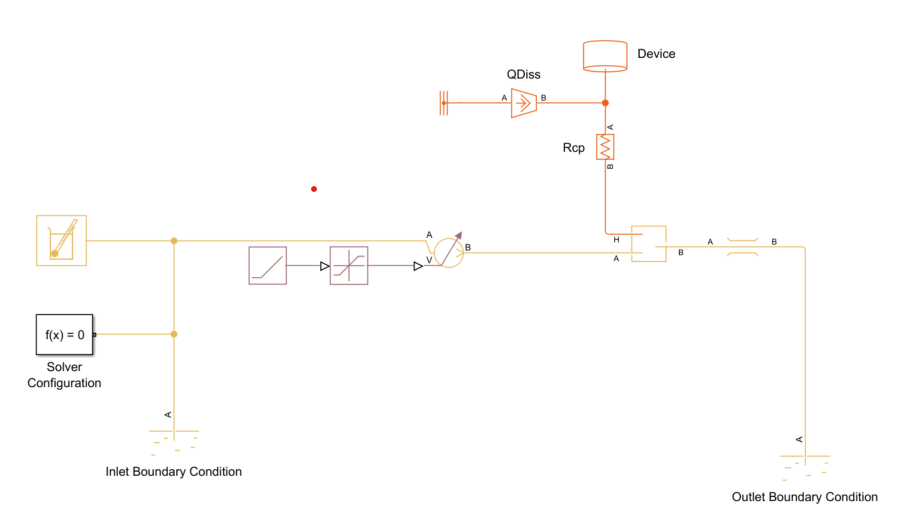

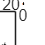

simInp = Simulink.SimulationInput("example_Rcp_Chamber");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TChamberOut = simOut.simlog.Constant_Volume_Chamber_TL.B.T.series.values('degC');
TDevice     = simOut.simlog.Device.M.T.series.values('degC');

figure
plot(simOut.tout,[TChamberOut,TDevice])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax,TCoolantOutMax],'k:')
plot([simOut.tout(1),simOut.tout(end)],[TSurfaceMax,TSurfaceMax],'k:')

ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,In}','T_{Coolant,Out}','T_{Pipe,Internal}')
hold off

We can see the both the deivce temperature and the outlet temperature to reach both their maximum allowed values, confirming, the determined thermal resistance. 

#### Sizing the coldplate 

The thermal resistance will be a combination of the conductive resistance through the cold plate as well as the convective resistance from cold plate fluid channels to the cold plate. We will use a combination of [Pipe (TL)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/pipetl.html?s_tid=doc_ta) block and [Conductive Heat Transfer](https://www.mathworks.com/help/releases/R2025a/simscape/ref/conductiveheattransfer.html?s_tid=doc_ta) to model the behaviour between cooled device and the cooling fluid. 

We will use the following definitions for a cold plate with rectangular channels:

cpLength            = 250; % (mm)
cpWidth             = 150; % (mm)
cpThickness         = 6;   % (mm)
deviceD             = 75; % mm

channelWidth    = 5;   % (mm)
channelHeight   = 5;   % (mm)
numPasses       = 15;  % 
effFlowLength   = 220; % (mm)
cpK             = 167; % (W/(m*K))

cpDeviceSurfaceArea   = pi*(deviceD/2)^2; % mm^2
channelLength         = numPasses*effFlowLength/1000; % (m) 
channelArea           = channelHeight*channelWidth; % Channel cross-sectional area (mm^2)
channelDh             = 2*channelWidth*channelHeight/(channelHeight+channelWidth); % (mm)
channelRoughness      = 15e-6; % (m)
channelHTCSurfaceArea = channelLength*2*(channelWidth*1e-3+channelHeight*1e-3); % Channel surface area for convective heat transfer (m^2)

The convective heat transfer coefficient in the cold channels can be determined using the Gnielinksi correlation. This is the same approach that is being used inside the Pipe (TL) component. For simplicity, we are using the fluid properties at an assumed inlet temperature of 25°C. This is then used to determine the thermal resistance of the convective heat transfer path. 

htc = calculateHTCPipe(channelDh*1e-3,channelArea*1e-6, mDot, 2000, 4000, kCoolant,channelRoughness/(channelDh*1e-3),muCoolant,PrCoolant);
Rconv  = 1/(htc*channelHTCSurfaceArea);

The thermal resistance due to conduction is then determined using the cold plate specifications and its material properties

Rcond  = cpThickness*1e-3/(cpK*cpDeviceSurfaceArea*1e-6);

The two combines give the total resistance

Rtotal = Rconv+Rcond;

This is well within what is needed for the given sizing, we can again validate this using a Simscape model. 

open_system("example_ColdPlate")

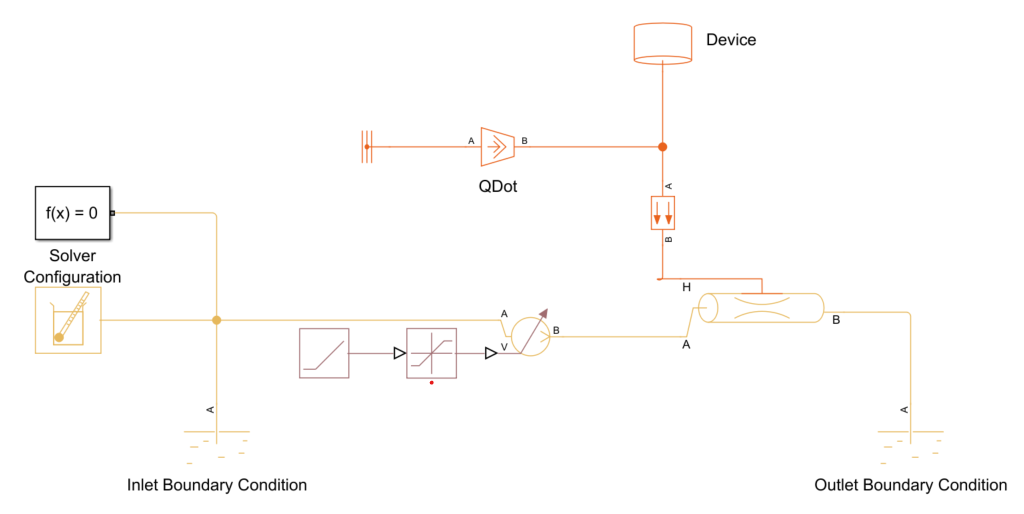

The Pipe (TL) block and the Conductive Heat Transfer block are parmaterized using the above values. The remaining blocks in the thermal fluid domain (the two reservoirs as well as the mass flow rate block) all also have a parameter to define the cross-sectional area at their respective ports. This is the area that is used for the already mentioned [Upwinding Numerical Scheme](https://www.mathworks.com/help/releases/R2025a/hydro/ug/simscape-fluids-numerical-scheme.html?searchPort=50807). To avoid discontinuities, especially in flow reversals smoothing is applied to the calculations. The cross-sectional area parameter is used to scale the fluxes. If the model is epxected to have small or near-zero flow rates for a longer time, the contribution of conduction to the flow might become more noticeable. The port cross-sectional area can scale this behevaor (See also [Impact of Upwind Smoothing on Energy Flow Rate](https://www.mathworks.com/help/releases/R2025a/hydro/ug/simscape-fluids-numerical-scheme.html#mw_3d058a58-efa2-479f-9d78-c271aed1804e)). It is good practice to have cross-sectional areas of connected components to be of the same size or roughly the same size. See also [Specifying the Cross-Sectional Area at Ports](https://www.mathworks.com/help/simscape/ug/fluid-system-modeling.html#mw_b4748c31-a3fc-4eab-82ca-58153af32e91)). In this model all connected areas are set to the cold plate channel cross-sectional area. 

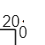

simInp = Simulink.SimulationInput("example_ColdPlate");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TColdPlateOut = simOut.simlog.Pipe_TL.B.T.series.values('degC');
TDevice       = simOut.simlog.Device.M.T.series.values('degC');

figure
plot(simOut.tout,[TColdPlateOut,TDevice])
hold on
plot([simOut.tout(1),simOut.tout(end)],[TCoolantOutMax,TCoolantOutMax],'k:')
plot([simOut.tout(1),simOut.tout(end)],[TSurfaceMax,TSurfaceMax],'k:')

ylabel('T [°C]')
xlabel('Time [s]')
legend('T_{Coolant,In}','T_{Coolant,Out}','T_{Pipe,Internal}')
hold off

#### Determine cold plate pressure drop

We will proceed with the cold plate specification as above. With the maximum flow rate we can determine the expected pressure drop, which will be used later to size the pump. We will use the model from the previous step which is already parameterized correctly.

open_system("example_ColdPlate")

The Pipe (TL) block uses a Haaland approximation to calculate the Darcy friction factor for turbulent flow. For laminar flow, it uses a constant shape factor. The parameter Aggregate equivalent length of local resistances, can be used to account for additional resistrances for example due to bends, resistances and other pipe fittings. Here we are assuming this length to be zero. 

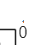

simInp = Simulink.SimulationInput("example_ColdPlate");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pColdPlateIn    = simOut.simlog.Pipe_TL.A.p.series.values('Pa');
pColdPlateOut   = simOut.simlog.Pipe_TL.B.p.series.values('Pa');

dpColdPlate     = pColdPlateIn-pColdPlateOut;

figure
plot(simOut.tout,[pColdPlateIn,pColdPlateOut])
ylabel('p [Pa]')
xlabel('Time [s]')
legend('p_{Coolant,In}','p_{Coolant,Out}')
hold off


disp(dpColdPlate(end))

   1.4826e+05



At steady state for the maximum flow rate, the current cold plate design produces a pressure drop of roughly 1.5 bar. 